clear
T_1 = -20; %C
% T_2 = ? %
T_4 = -10; %C

% p_1 = 1.338 % bar % tryk


% rho = 6.76 % kg


%%%%%%%%%%%%%%          R134a        %%%%%%%%%%%%%%%%%%%%%
%                         R1

% L = sym('L') %, 'positive'
syms L
% L = 1.5 % m
nu = 0.000001511; %m^2 / s

eta_1 = 0.00001022; %kg/(m*s)

q_m = 0.00338; %kg/s

d_1 = (9.52 - 2 * 0.8) / 1000 % m %indre diameter af kobber rør

d_1 = 0.0079


g = 9.82; % m/s^2

lambda_1 = 0.01036 %[W/m-K]

lambda_1 = 0.0104


r_fordamp = 211.2 * 1000% J/kg%m * l_fd

r_fordamp = 211200




Re_1 = q_m * d_1 / (pi/4 * d_1^2 * eta_1)

Re_1 = 5.3168e+04


K_f = r_fordamp / (L * g) 

$$K\_f = \frac{10560000}{491\,L}$$

 
NUs_1 = 0.0075 * (Re_1^2 * K_f )^0.40

$$NUs\_1 = \frac{3\,{\left(\frac{61135765364151616875}{1005568\,L}\right)}^{2/5}}{400}$$


alpha_1 = NUs_1 * lambda_1 / d_1;
alpha_1_ = vpa(alpha_1,3)

$$alpha\_1\_ = 0.00981\,{\left(\frac{6.08e+13}{L}\right)}^{2/5}$$


A_1 = pi*d_1*L

$$A\_1 = \frac{99\,\pi \,L}{12500}$$


R_1 = vpa(1 / (alpha_1 * A_1), 3) % K/W

$$R\_1 = \frac{4100.0}{L\,{\left(\frac{6.08e+13}{L}\right)}^{2/5}}$$




%%%%%%%%%%%%%%%%%%%%%  Kobber rør   %%%%%%%%%%%%%
%                         R2

r_1 = d_1/2 % m % indre radius

r_1 = 0.0040

d_2 = 9.52 / 1000 % m ydre diamter af rør

d_2 = 0.0095

r_2 = d_2 /2  % m % ydre radius

r_2 = 0.0048


lambda_2 = 372; % W/(m*K) Tabel 10.11 i thermo bog version 4


R_2 = (r_2 / r_1) / (lambda_2 * 2 * pi * L)

$$R\_2 = \frac{119}{73656\,L\,\pi }$$



%%%%%%%%%%%%%%%%%%%%    Brine  20% saltblanding NaCl  %%%%%%%%%%%%%%%%%
%                       R3

T_3 =  -18; % C gæt

nu_3 = 0.000003921; %[m^2/s]
c_p_3 = 3.354 * 1000; %[J/Kg * K]
rho_3 = 1162; % kg/m^3
lambda_3 = 0.5172; % W/(m*K)

a_3 = lambda_3 / (c_p_3 * rho_3)

a_3 = 1.3271e-07

beta_3 =  0.000021; %1/K  % chat bot

Ra = (g * beta_3 * (T_4 - T_3) * d_2^3) / (nu^2 * a_3)

Ra = 4.6980e+09


% n_3 = 1/4; % 1/3 for turbolent % 1/4 for laminart
% C_3 = 0.10 % % turbulent strømning
% NUs_3 = C_3 * Ra^n_3

eta_3 = nu_3/rho_3

eta_3 = 3.3744e-09


Pr_3 = eta_3 * c_p_3 / lambda_3

Pr_3 = 2.1882e-05


NUs_3 = (0.60 + (0.387 * Ra^(1/6)) / (1 + (0.559/Pr_3)^(9/16))^(8/27) )^2

NUs_3 = 12.3590


alpha_3 = NUs_3 * lambda_3 / d_2 

alpha_3 = 671.4338


A_3 = pi * d_2 * L

$$A\_3 = \frac{119\,\pi \,L}{12500}$$


R_3 = 1 / (alpha_3 * A_3)

$$R\_3 = \frac{109951162777600000}{702813254761023567\,L\,\pi }$$


Phi_slush = 230 %

Phi_slush = 230


R_tot_indre = R_1 + R_2 + R_3

$$R\_tot\_indre = \frac{2727399207621155801491}{17255471030892650616984\,L\,\pi }+\frac{4096.652331829071044921875}{L\,{\left(\frac{60797246297088.0}{L}\right)}^{2/5}}$$


R_ydre = 0.437 % K/W 

R_ydre = 0.4370


T_4 = -2

T_4 = -2


R_tot_eq1 = (R_1 + R_2 + R_3) %+ R_ydre;

$$R\_tot\_eq1 = \frac{2727399207621155801491}{17255471030892650616984\,L\,\pi }+\frac{4096.652331829071044921875}{L\,{\left(\frac{60797246297088.0}{L}\right)}^{2/5}}$$

R_tot_eq2 = (T_4 - T_1) / Phi_slush;

L_fordamp = solve(R_tot_eq1 == R_tot_eq2, L)

$$L\_fordamp = 0.78879692000840609576949502054299$$



% for i = 1:20
%     T = -5:0.5:4.5;
%     R_tot_eq1 = R_1 + R_2 + R_3 + R_ydre;
%     R_tot_eq2 = (T_1 - T(i)) / Phi_slush;
%     L_fordamp(i) = double(solve(R_tot_eq1 == R_tot_eq2, L)); 
% end


% L_fun = R_tot_eq1 - R_tot_eq2

% plot(T,L_fordamp)



L = linspace(0.1,4,100)%0.1:0.1:2;

L =     0.1000    0.1394    0.1788    0.2182    0.2576    0.2970    0.3364    0.3758    0.4152    0.4545    0.4939    0.5333    0.5727    0.6121    0.6515    0.6909    0.7303    0.7697    0.8091    0.8485    0.8879    0.9273    0.9667    1.0061    1.0455    1.0848    1.1242    1.1636    1.2030    1.2424    1.2818    1.3212    1.3606    1.4000    1.4394    1.4788    1.5182    1.5576    1.5970    1.6364    1.6758    1.7152    1.7545    1.7939    1.8333    1.8727    1.9121    1.9515    1.9909    2.0303


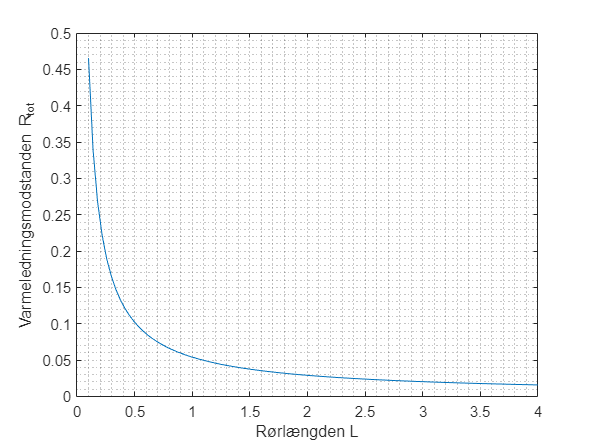


for i = 1:100

nu = 0.000001511; %m^2 / s

eta_1 = 0.00001022; %kg/(m*s)

q_m = 0.00338; %kg/s

d_1 = (9.52 - 2 * 0.8) / 1000 ;% m %indre diameter af kobber rør

g = 9.82; % m/s^2

lambda_1 = 0.01036; %[W/m-K]

r_fordamp = 211.2 * 1000;% J/kg%m * l_fd



Re_1 = q_m * d_1 / (pi/4 * d_1^2 * eta_1);

K_f = r_fordamp / (L(i) * g) ;
 
NUs_1 = 0.0075 * (Re_1^2 * K_f )^0.40;

alpha_1 = NUs_1 * lambda_1 / d_1;
alpha_1_ = vpa(alpha_1,3);

A_1 = pi*d_1*L(i);

R_1 = vpa(1 / (alpha_1 * A_1), 3); % K/W



%%%%%%%%%%%%%%%%%%%%%  Kobber rør   %%%%%%%%%%%%%
%                         R2

r_1 = d_1/2; % m % indre radius
d_2 = 9.52 / 1000; % m ydre diamter af rør
r_2 = d_2 /2 ; % m % ydre radius

lambda_2 = 372; % W/(m*K) Tabel 10.11 i thermo bog version 4


R_2 = (r_2 / r_1) / (lambda_2 * 2 * pi * L(i));


%%%%%%%%%%%%%%%%%%%%    Brine  20% saltblanding NaCl  %%%%%%%%%%%%%%%%%
%                       R3

T_3 =  -18; % C gæt

nu_3 = 0.000003921; %[m^2/s]
c_p_3 = 3.354 * 1000; %[J/Kg * K]
rho_3 = 1162; % kg/m^3
lambda_3 = 0.5172; % W/(m*K)

a_3 = lambda_3 / (c_p_3 * rho_3);
beta_3 =  0.000021; %1/K  % chat bot

Ra = (g * beta_3 * (T_4 - T_3) * d_2^3) / (nu^2 * a_3);

% n_3 = 1/4; % 1/3 for turbolent % 1/4 for laminart
% C_3 = 0.10 % % turbulent strømning
% NUs_3 = C_3 * Ra^n_3

eta_3 = nu_3/rho_3;

Pr_3 = eta_3 * c_p_3 / lambda_3;

NUs_3 = (0.60 + (0.387 * Ra^(1/6)) / (1 + (0.559/Pr_3)^(9/16))^(8/27) )^2;

alpha_3 = NUs_3 * lambda_3 / d_2 ;

A_3 = pi * d_2 * L(i);

R_3 = 1 / (alpha_3 * A_3);


R_tot(i) = (R_1 + R_2 + R_3);

end

plot(L,R_tot)
ylabel('Varmeledningsmodstanden R_{tot}')
xlabel('Rørlængden L')
grid('minor')